# LAB DSP

Given 𝑓𝑠 = 200 Hz, design the following digital filters:

### a) Second order Butterworth LPF with 𝑓𝑐 = 5 Hz

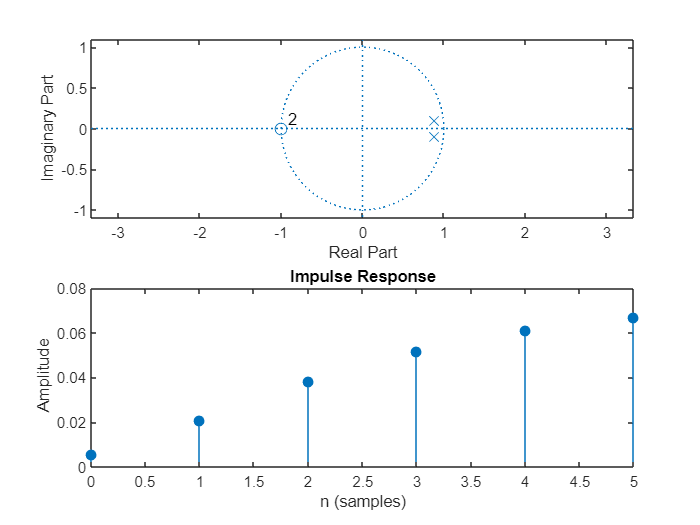

clear
syms z
fs = 200;
fc = 5;
[b_butter,a_butter] = butter(2, fc/(fs/2));
figure('Color','w')
subplot 211
zplane(b_butter, a_butter)
subplot 212
impz(b_butter, a_butter, 6)

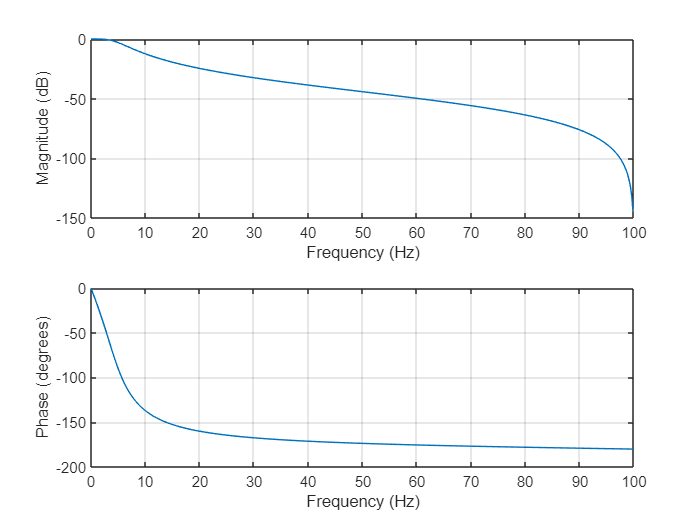

figure('Color','w')
freqz(b_butter, a_butter,[],fs)

sys_butter = filt(a_butter, b_butter);
[Num,Den] = tfdata(sys_butter);
sys_syms_butter = poly2sym(cell2mat(Num),z)/poly2sym(cell2mat(Den),z);
diff_eq_butter = iztrans(sys_syms_butter)

$$diff\_eq\_butter = \frac{2178232917322382848\,{\left(-1\right)}^{n}}{3195158932843533}+\frac{461631296143486528\,\delta_{n,0}}{3195158932843533}+\frac{687801153720815296\,{\left(-1\right)}^{n}\,\left(n-1\right)}{1065052977614511}$$

### b) IIR HPF with 𝑓𝑐 = 1 Hz designed directly on the z-plane.

iir_filter = (z-1)^2 / (z-0.9315)^2;
b_iir = [1 -2 1];
a_iir = [1 -1.863 0.8677];
sys_iir = filt(a_iir, b_iir);
[Num,Den] = tfdata(sys_iir);
sys_syms_iir = poly2sym(cell2mat(Num),z)/poly2sym(cell2mat(Den),z);
%diff_eq_iir = iztrans(iir_filter)
diff_eq_iir = iztrans(sys_syms_iir)

$$diff\_eq\_iir = \frac{47\,n}{10000}+\frac{8677\,\delta_{n,0}}{10000}+\frac{1323}{10000}$$

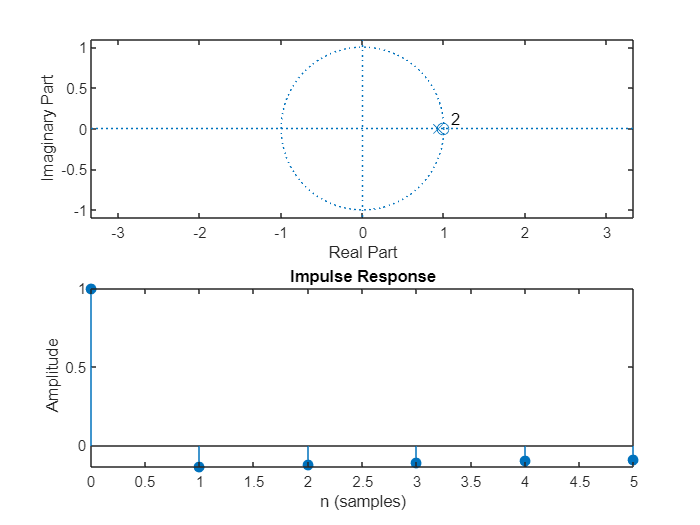

figure('Color','w')
subplot 211
zplane(b_iir, a_iir)
subplot 212
impz(b_iir, a_iir, 6)

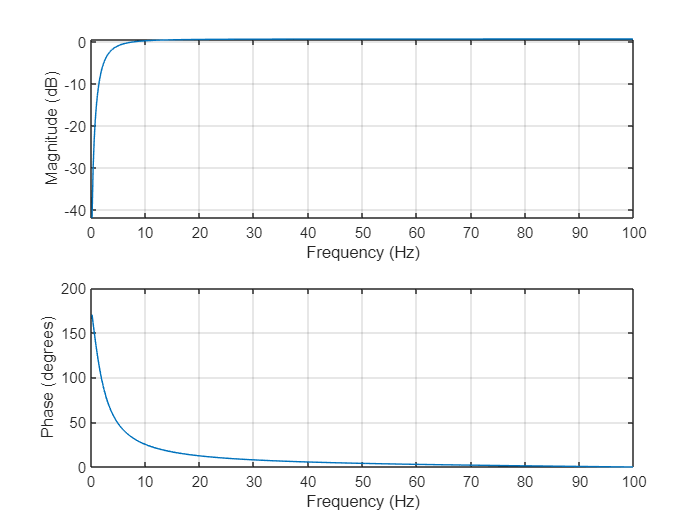

figure('Color','w')
freqz(b_iir, a_iir, [], fs)

### c) Fourth order Moving Average (get the 𝑓𝑐 for such a filter)

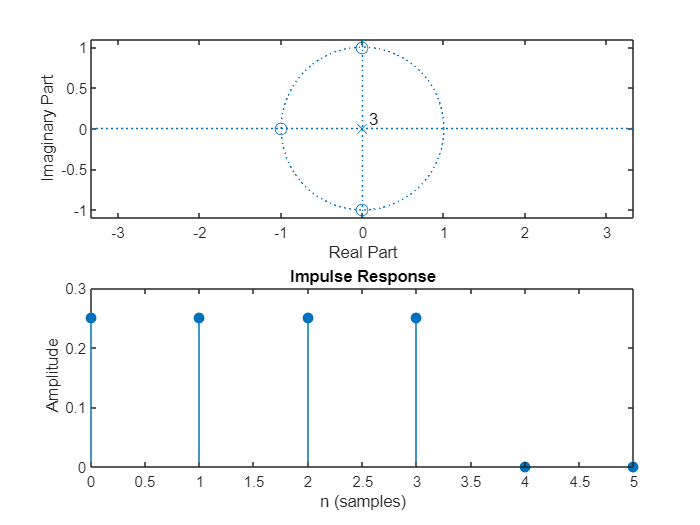

b_avg = [0.25 0.25 0.25 0.25];
a_avg = 1;
figure('Color','w')
subplot 211
zplane(b_avg, a_avg)
subplot 212
impz(b_avg, a_avg, 6)

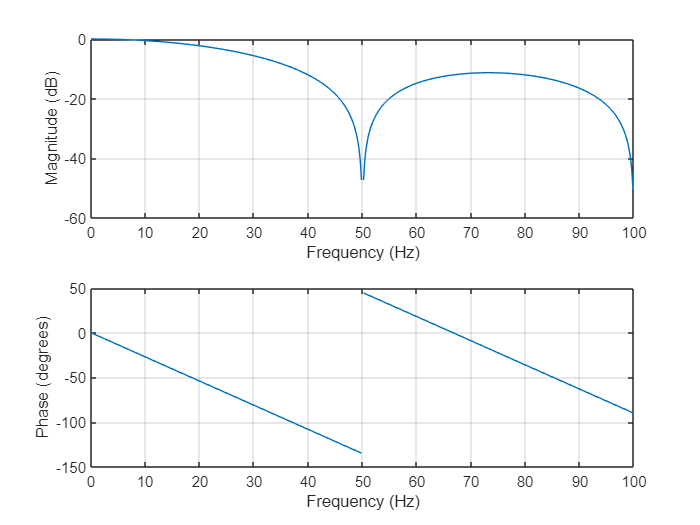

figure('Color','w')
freqz(b_avg, a_avg, [], fs)

sys_avg = filt(b_avg, a_avg);
[Num,Den] = tfdata(sys_avg);
sys_syms_avg = poly2sym(cell2mat(Num),z)/poly2sym(cell2mat(Den),z);
diff_eq_avg = iztrans(sys_syms_avg)

$$diff\_eq\_avg = \frac{\delta_{n-1,0}}{4}+\frac{\delta_{n-2,0}}{4}+\frac{\delta_{n-3,0}}{4}+\frac{\delta_{n,0}}{4}$$

### 3. Create a signal vector that represents a 2 Hz square signal that goes from 0 to 1.65 V and  apply the filters directly on MATLAB with the filter function.

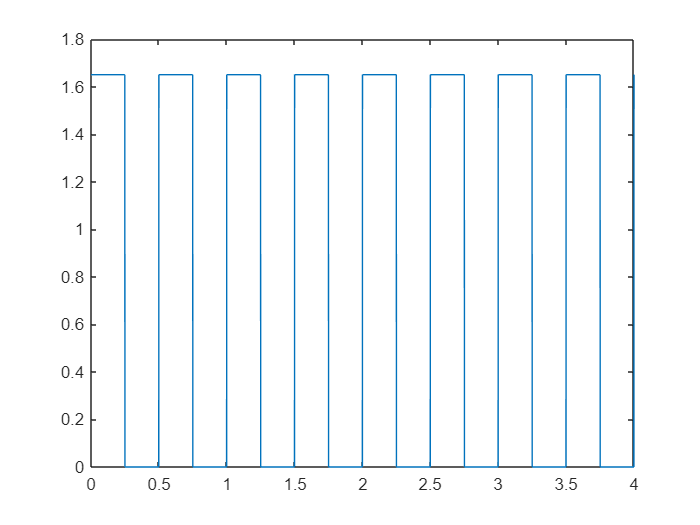

t = 0:0.001:4;
f_square = 2;
amp = 1.65 * 0.5 ;
square_signal = amp * square(t*2*pi*f_square) + amp;
plot(t, square_signal)

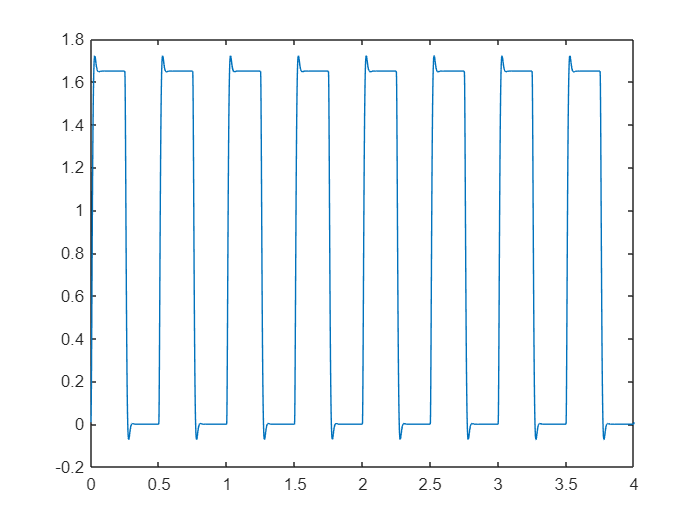

square_signal_butter = filter(b_butter, a_butter, square_signal);
plot(t, square_signal_butter)

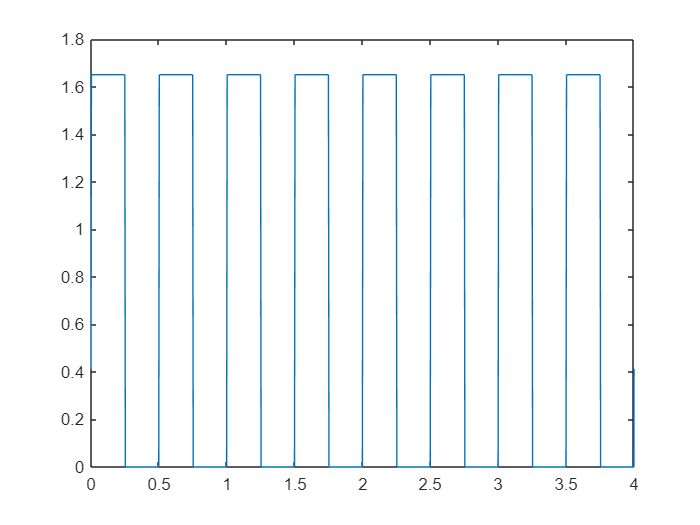

square_signal_avg = filter(b_avg, a_avg, square_signal);
plot(t, square_signal_avg)

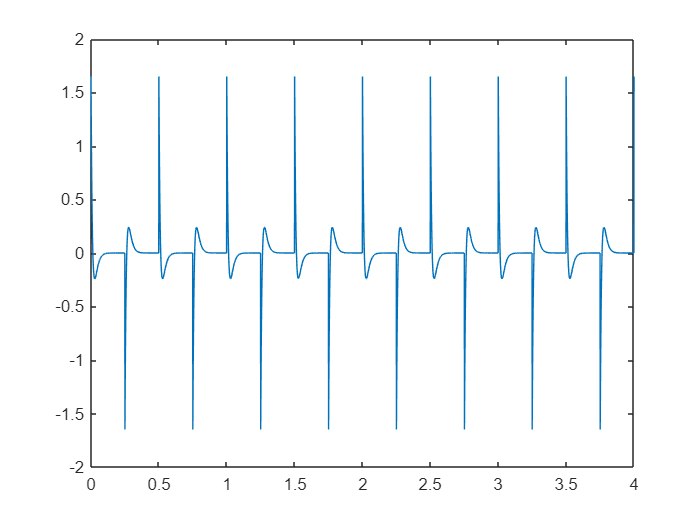

square_signal_iir = filter(b_iir, a_iir, square_signal);
plot(t, square_signal_iir)

### ***4. Obtain the FFT and PSD of both the input and output signals.***

#### Señal pelona

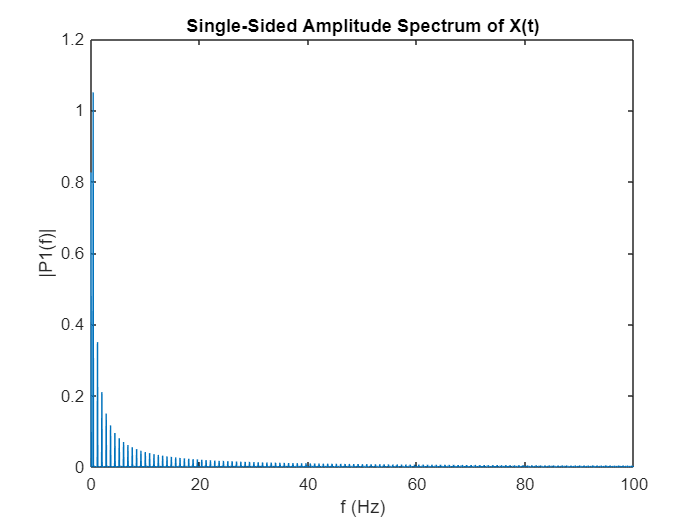

plotFFT(square_signal,fs)

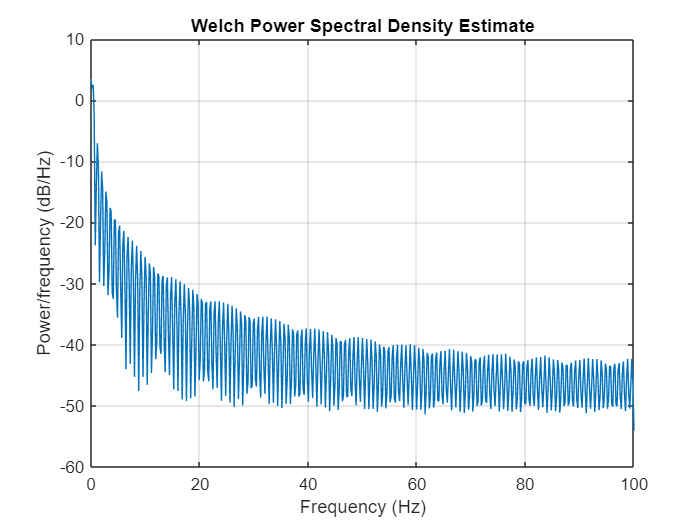

pwelch(square_signal, [], [], [], fs)

#### Butter

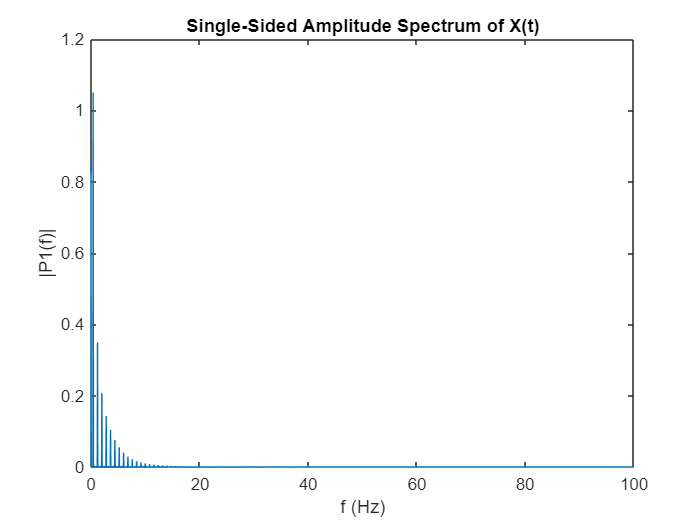

plotFFT(square_signal_butter,fs)

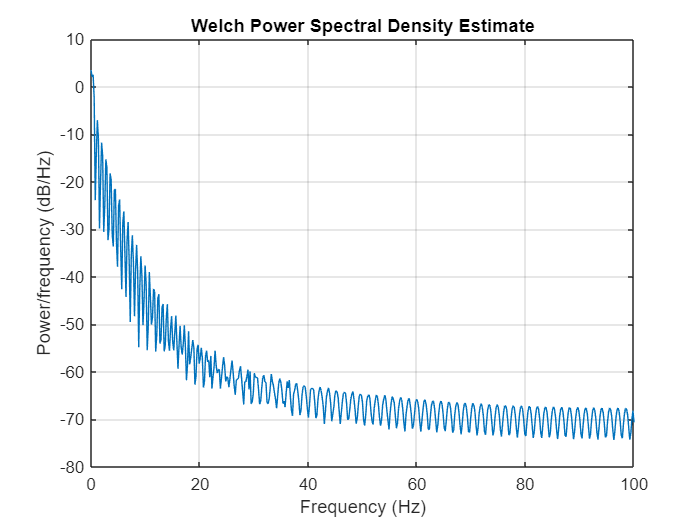

pwelch(square_signal_butter, [], [], [], fs)

#### Avg

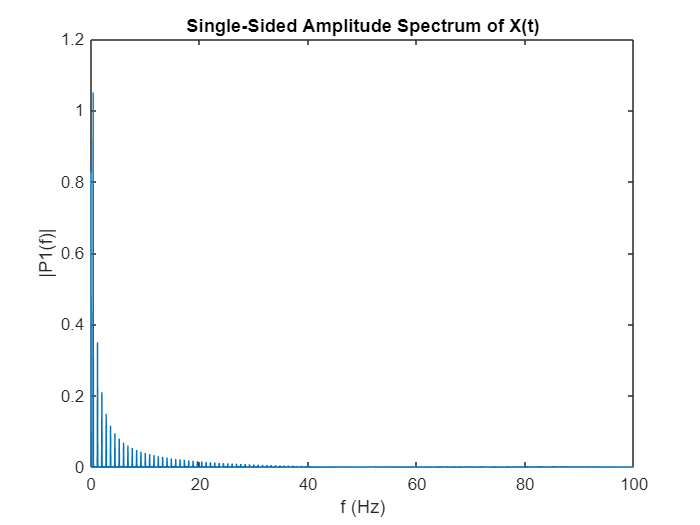

plotFFT(square_signal_avg,fs)

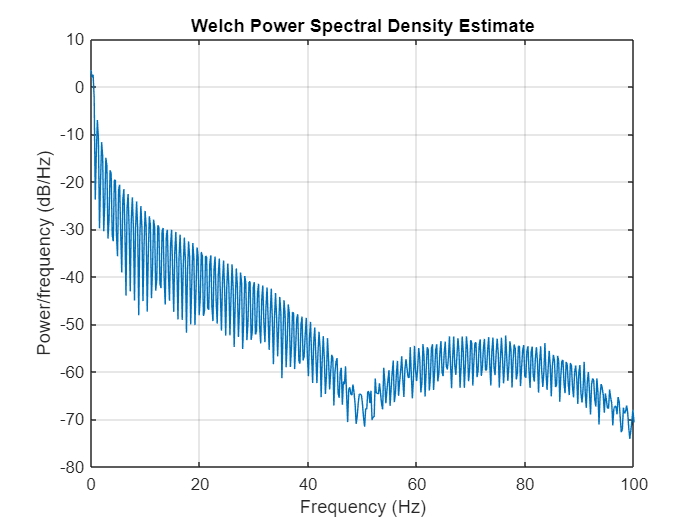

pwelch(square_signal_avg, [], [], [], fs)

#### IIR

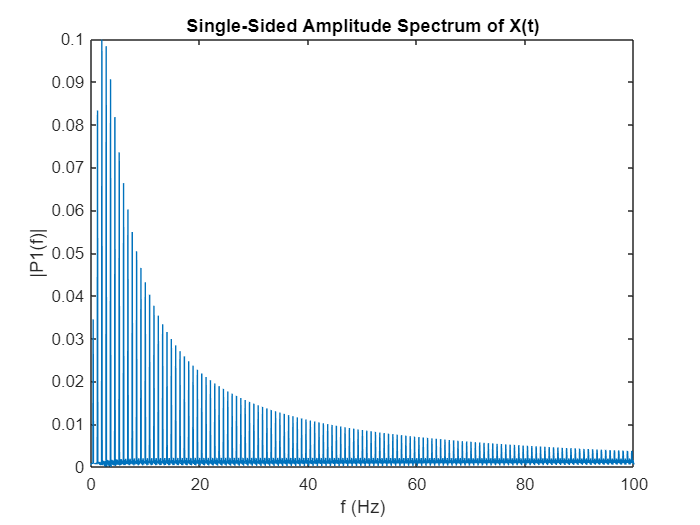

plotFFT(square_signal_iir,fs)

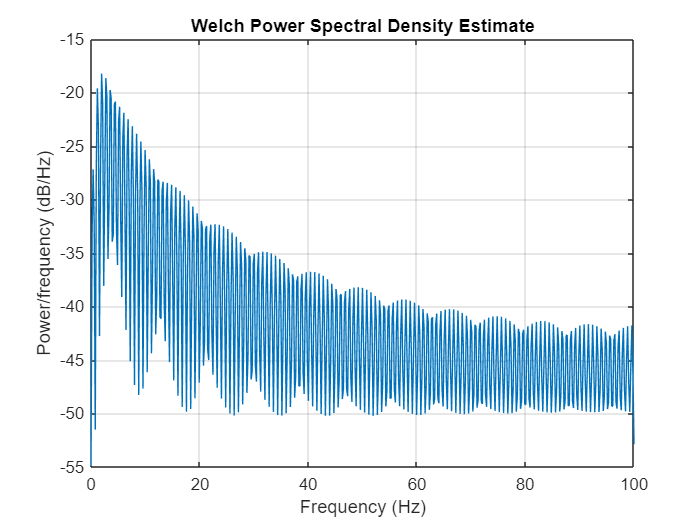

pwelch(square_signal_iir, [], [], [], fs)